# EE141 Digital Signal Processing

# Lab 3: Basic Second Order Filters

# Lab Section: 022

# Name: Buddy Ugwumba SID: 862063029

## Objective

Gain hands on experience processing a real-world music signal. 

% Loads the MATLAB file
load ride
% Use audioplayer function to load the file
p = audioplayer(audio_sample, fs);
play(p)

a) For general $a$ and $c$, determine the impulse resonse $h\left\lbrack n\right\rbrack$

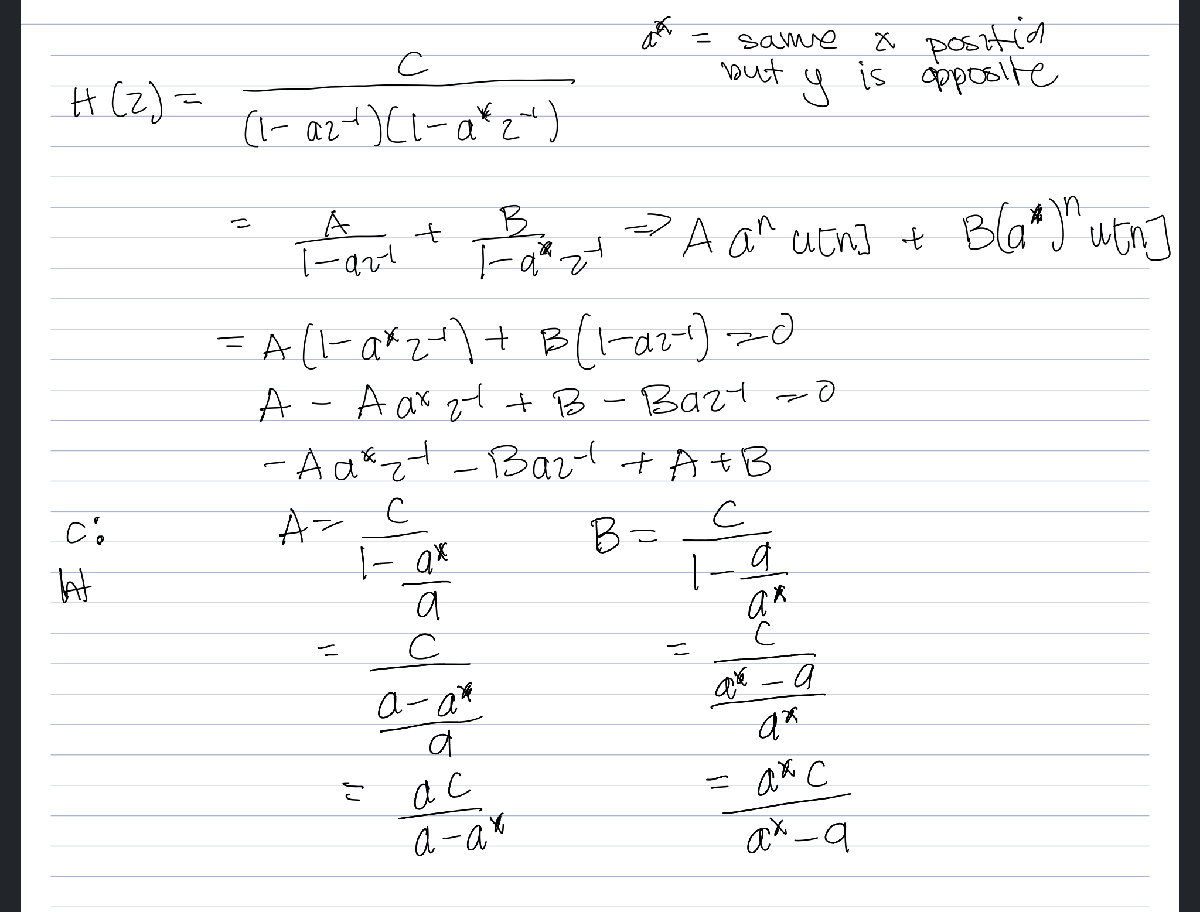

b) Appropriately choosing $a$ and $c$ to make h[n] a lowpass filter. 

a = 0.8 - 0.001j;
c = (1-a)*(1-conj(a));
% Apply h[n] to x[n] (music signal)
% h => conv()
n = 0:100;
% impulse response h[n]
h1 = ((c/(1-(a/conj(a))).*a.^(n))+ ((c/(1-(conj(a)/a))).*conj(a).^(n)));

% audio_sample(:,1) => first channel
Y_1(:,1) =  conv(audio_sample(:,1), h1, 'same');
% the second output
Y_1(:,2) = conv(audio_sample(:,2), h1, 'same');
p2 = audioplayer(Y_1, fs);
%play(p2)

Yes, I do hear a muffled verion of the original audio file. 

c) Using the fft command, take the DTFT of both the input and the output of one of the channels. Plot their magnitudes side by side. 

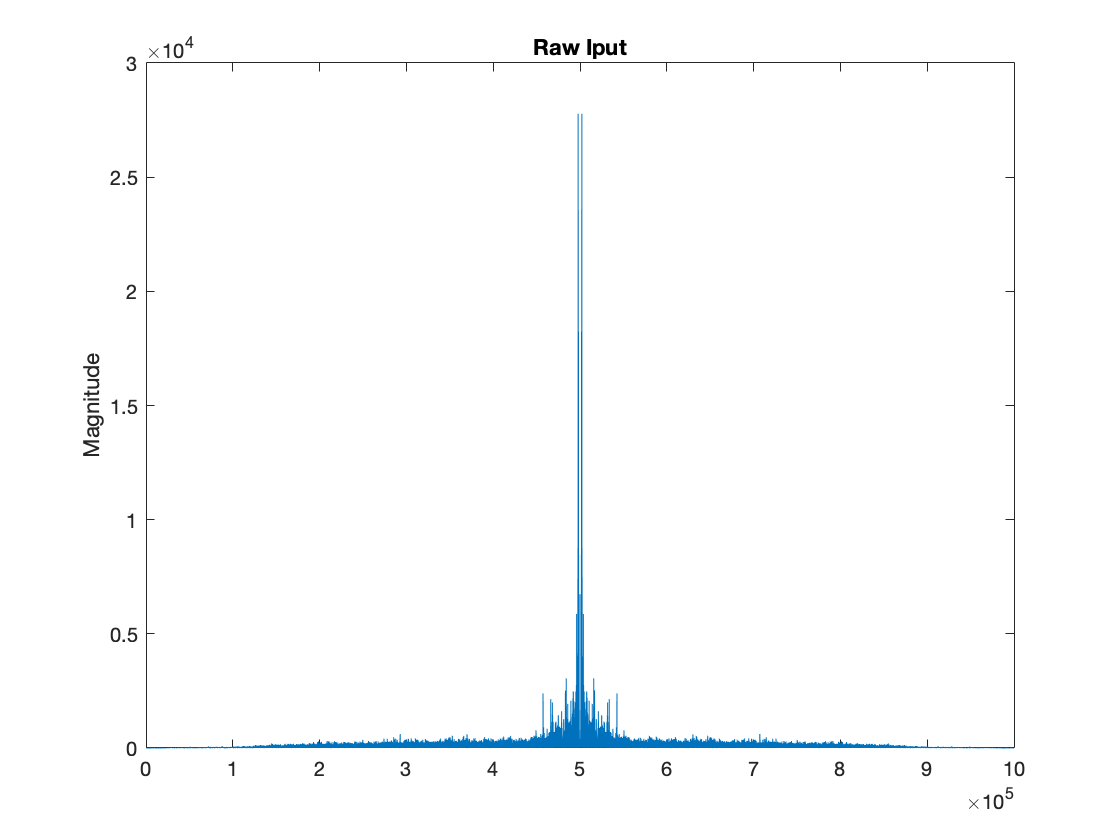

figure
plot(fftshift(abs(fft(audio_sample(:,1)))))
title('Raw Iput')
ylabel('Magnitude')
hold on;

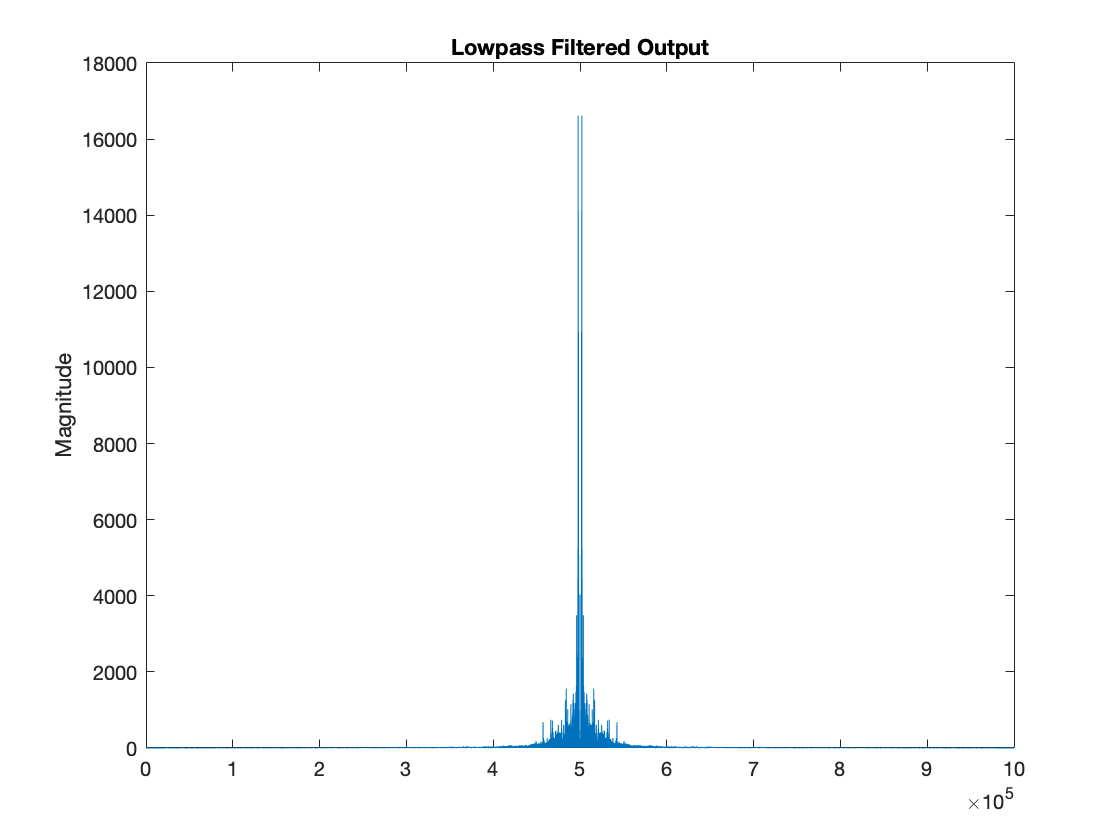

figure
plot(fftshift(abs(fft(Y_1(:,1)))))
title('Lowpass Filtered Output')
ylabel('Magnitude')

Yes I see the high frequencies supressed at the tail end of the plot. The delay, after passing the signal through the low-pass filter is seen on the x-axis. This is why the signal starts at 5. 

d) Repeat b and c with a highpass filter. '

a = -0.8 - 0.001j;
c = (1-a)*(1-conj(a));
% Apply h[n] to x[n] (music signal)
% h => conv()
n = 0:100;
% impulse response h[n]
h1 = ((c/(1-(a/conj(a))).*a.^(n))+ ((c/(1-(conj(a)/a))).*conj(a).^(n)));

% audio_sample(:,1) => first channel
Y_1(:,1) =  conv(audio_sample(:,1), h1, 'same');
% the second output
Y_1(:,2) = conv(audio_sample(:,2), h1, 'same');
p2 = audioplayer(Y_1, fs);
%play(p2)

figure
plot(fftshift(abs(fft(audio_sample(:,1)))))
title('Raw Iput')
ylabel('Magnitude')
hold on;

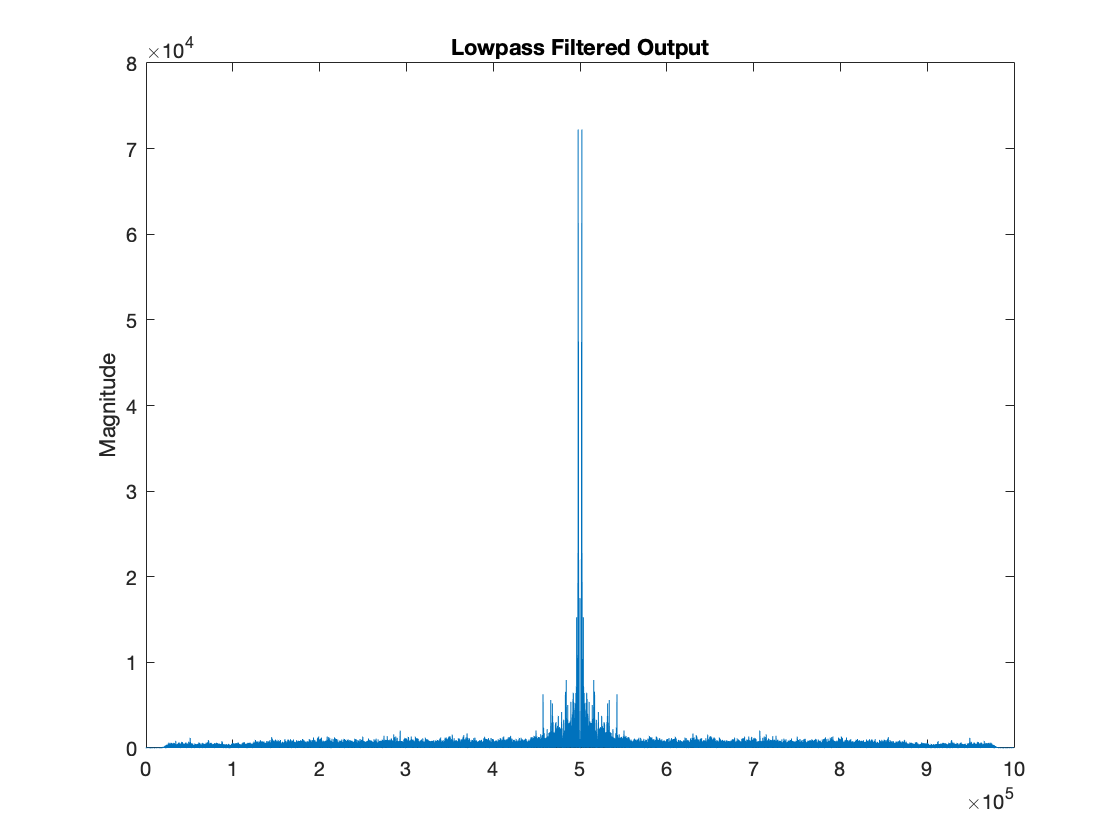


figure
plot(fftshift(abs(fft(Y_1(:,1)))))
title('Highpass Filtered Output')
ylabel('Magnitude')

Yes, I do see that the high frequencies are more prominent. 

e) Repeat b and c with a bandpass filter. 

a = 0 - 0.001j;
c = (1-a)*(1-conj(a));
% Apply h[n] to x[n] (music signal)
% h => conv(1j
n = 0:100;
% impulse response h[n]
h1 = ((c/(1-(a/conj(a))).*a.^(n))+ ((c/(1-(conj(a)/a))).*conj(a).^(n)));

% audio_sample(:,1) => first channel
Y_1(:,1) =  conv(audio_sample(:,1), h1, 'same');
% the second output
Y_1(:,2) = conv(audio_sample(:,2), h1, 'same');
p2 = audioplayer(Y_1, fs);
play(p2)

figure
plot(fftshift(abs(fft(audio_sample(:,1)))))
title('Raw Iput')
ylabel('Magnitude')
hold on;

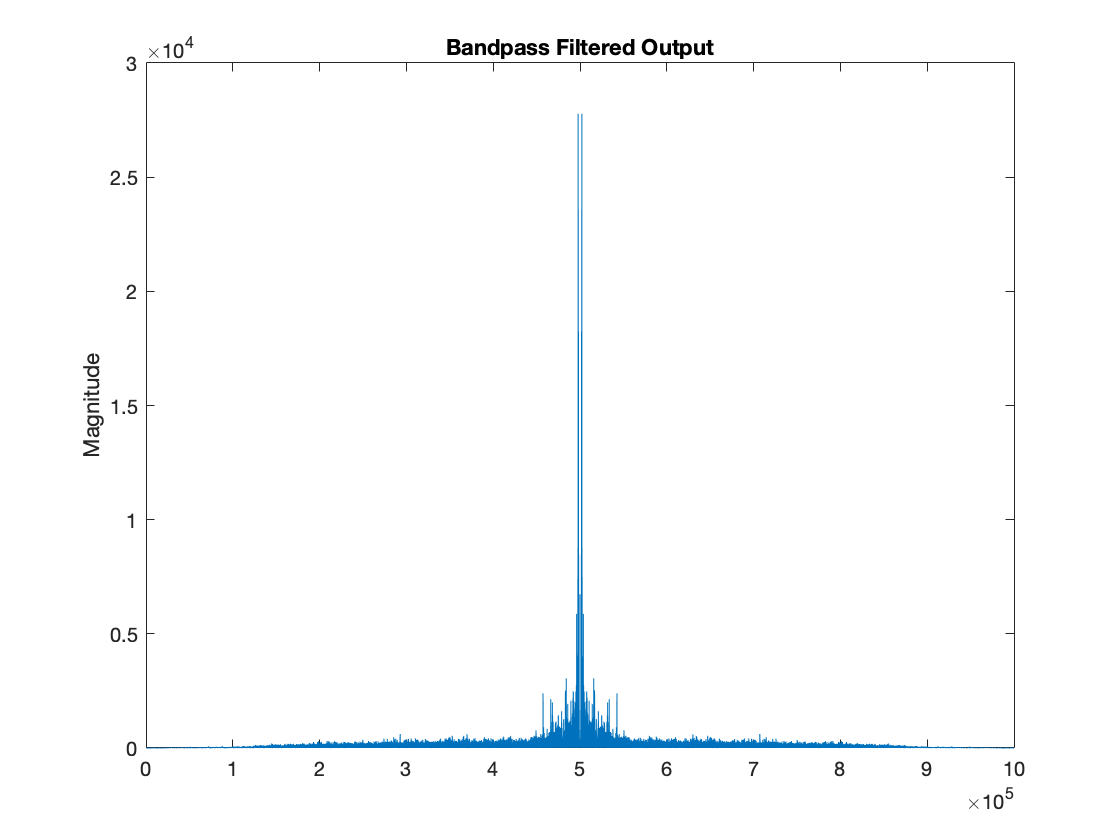

figure
plot(fftshift(abs(fft(Y_1(:,1)))))
title('Bandpass Filtered Output')
ylabel('Magnitude')